# **Cinemática Inversa Manipulador 4R**

# **Felipe Forero - Iván Hernández - Juan Ramirez - Felipe Zuleta**

Para el desarrollo del modelo cinemático inverso del manipulador, se utiliza un acercamiento geométrico del mismo.

Para encontrar las variables articulares del manipulador, se debe partir de la ubicación del TCP de la herramienta, para el desarrollo de este análisis comenzaremos observando el manipulador desde una vista superior, en donde las coordenadas x e y de la herramienta saltan a la vista, veáse la siguiente figura.

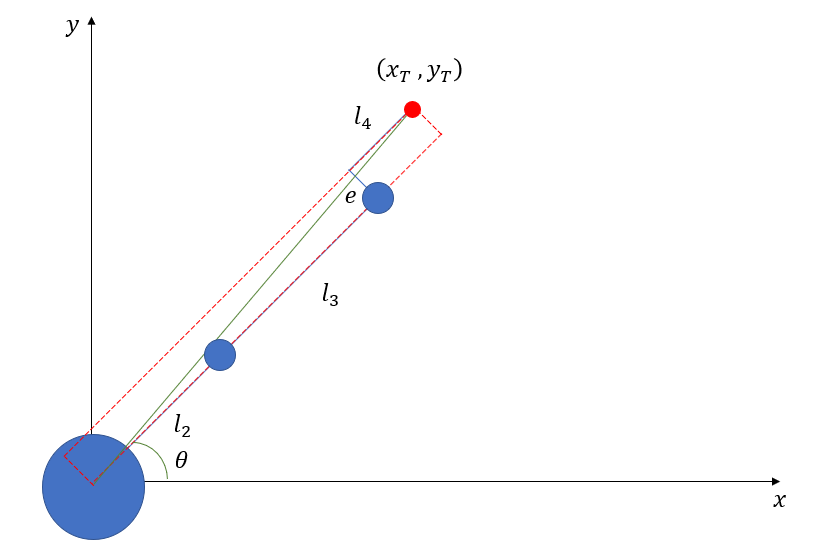

De la figura, se observa como el ángulo $\theta \;$ puede determinarse fácilmente.


$$\theta \;=\mathrm{atan2}\;\left(y_T \;,x_T \right)$$


syms xT yT
theta = atan2(yT,xT)

$$theta = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)$$

Por más que pareciera que este ángulo coincidiera con la variable articular para el primer eslabón, se sabe que esto no es correcto, y que su ángulo se puede determinar a partir de la siguiente figura.

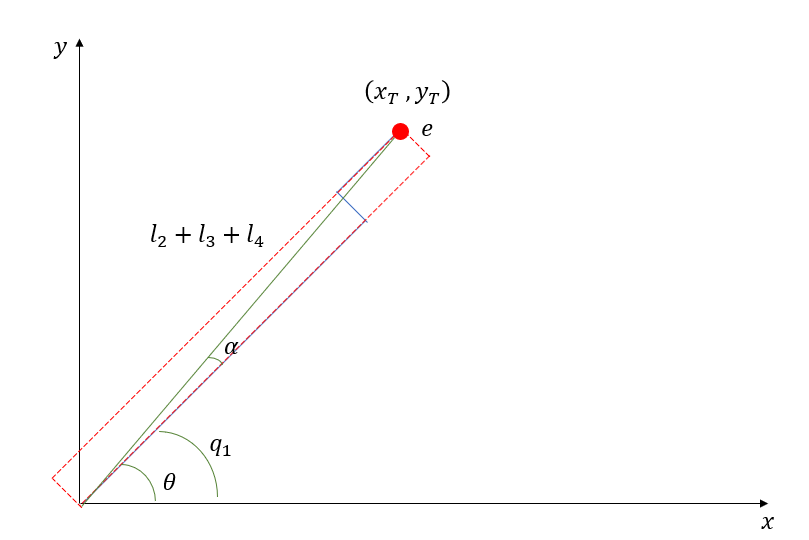

Con lo que se obtiene la expresión


$$q_1 =\theta -\alpha =\theta -\mathrm{atan2}\left(e\;,l_2 +l_3 +l_4 \right)$$


e = 5;
l2 = 10;
l3 = 8;
l4 = 5;

alpha = atan2(e,l2+l3+l4)

alpha = 0.2141

q1 = theta - alpha

$$q1 = \text{atan2}\left(\mathrm{yT},\mathrm{xT}\right)-\frac{7712348917861601}{36028797018963968}$$

Para continuar con el modelo cinemático inverso, se debe conocer la orientación deseada de la herramienta respecto al plano XY

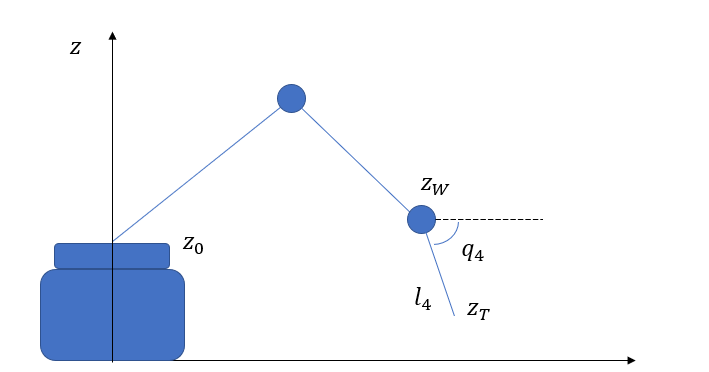

El objetivo, será conocer la posición de la muñeca, para lo que se comienza por conocer su altura.


$$z_W =z_T -l_4 \cdot \sin \;\left(q_4 \right)$$


Desde la vista superior se tiene.

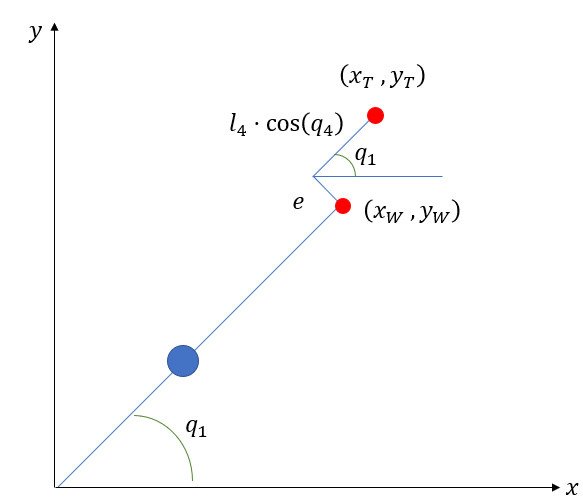

De donde, se encuentra la posición de la muñeca


$$x_W =x_T -l_4 \cdot \cos \left(q_4 \right)\cdot \cos \left(q_1 \right)+e\cdot \sin \left(q_1 \right)$$



$$y_W =y_T -l_4 \cdot \cos \left(q_4 \right)\cdot \sin \left(q_1 \right)-e\cdot \cos \left(q_1 \right)$$


De esta manera, los ángulos 2 y 3 pueden ser encontrados a través del teorema del coseno, para lo cual nos basamos en la figura

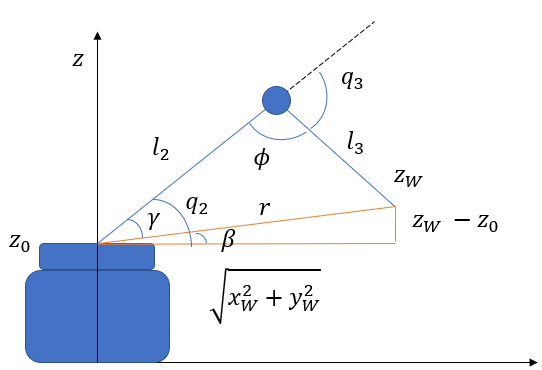

De esta manera, se encuentran los ángulos de interés a continuación.


$$\beta =\mathrm{atan2}\;\left(z_W -z_0 \;,\sqrt{\;x_w^2 +y_w^2 }\right)$$



$$r^2 =x_W^2 +y_W^2 +{\left(z_W -z_0 \right)}^2$$



$$\gamma =\cos^{-1} \left(\frac{l_2^2 +r^2 -l_3^2 }{2\cdot r\cdot l_2 }\right)$$



$$\phi \;{=\;\cos }^{-1} \left(\frac{l_2^2 +l_3^2 -r^2 }{2\cdot l_2 \cdot l_3 }\right)$$



$$q_2 =\beta +\gamma$$



$$q_3 =\pi -\phi \;$$
